# STOCHASTIC SIR MODEL PROCESSING

In this code, we will process data from a stochastic SIR model in order to predict a series of parameters. To achive such problem we first need to clean the data using a combination of 2 different cleaning methoods; moving average and neural networks. Once the data for each function (S,I,R) is processed we apply a genetic algorithm to calculate parameters of intrest. 

clear; clc; clf

## Load Data

Load discrete vectors respresenting suceptibles (S), infected (I) and removed ( R ) population evolving in time (t). It also loads the number total number of agents in the simulation (N). 

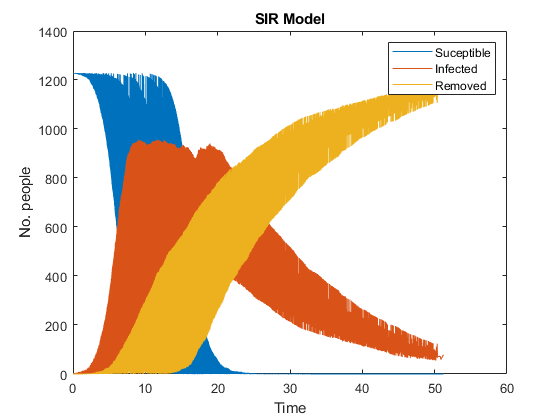

%Import stochastic S I R model. 
load("reto4.mat") %Load: S, I, R, N, t 

%Visualize
plot(t,S,t,I,t,R)
legend('Suceptible','Infected','Removed')
title('SIR Model')
xlabel('Time')
ylabel('No. people')

## Moving average

For the next section, we smooth out the model given in the previus section uning a mathood called moving average. 

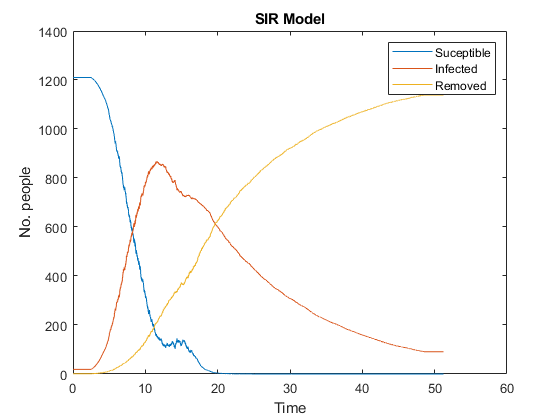

n = 1000;                   % Number of points to consider for the mean.  

S_ma = moving_ave(S,n);     %Smooth S
I_ma = moving_ave(I,n);     %Smooth I
R_ma = moving_ave(R,n);     %Smooth R

%Visualize
plot(t,S_ma,t,I_ma,t,R_ma)
legend('Suceptible','Infected','Removed')
title('SIR Model')
xlabel('Time')
ylabel('No. people')

## Nerural Networks

We use neural networks to smooth out even more the SIR model. In this section we take the model that moving average calculates and feed it to a neural network to smooth out even further. 

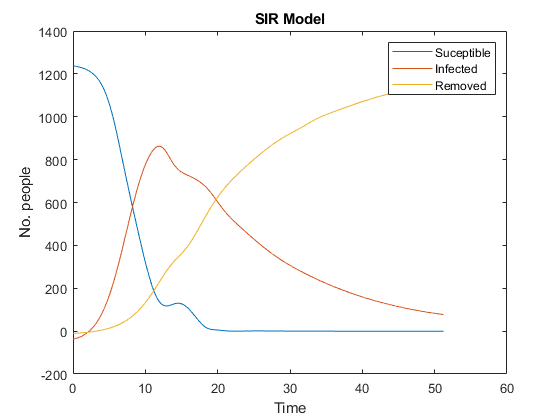

[S_smooth,  ~ ] = neuralnetwork_smoothfun(S_ma,t);  % 2nd S smooth
[I_smooth,  ~ ] = neuralnetwork_smoothfun(I_ma,t);  % 2nd I smooth
[R_smooth,  ~ ]  = neuralnetwork_smoothfun(R_ma,t); % 2nd R smooth

%Visualize 
plot(t,S_smooth,t,I_smooth,t,R_smooth)
legend('Suceptible','Infected','Removed')
title('SIR Model')
xlabel('Time')
ylabel('No. people')

## Genetic Algorithm

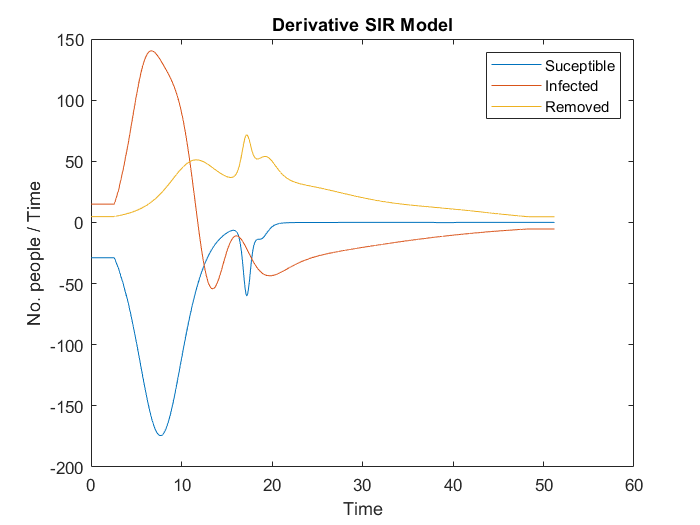

%The genetic algorithm for the sir model has the objective of finding the
%paremeters alpha and beta for a given but unknown SIR database.

%Calculate derivatives
S_prime = diff(S_smooth); S_prime = [0 S_prime./diff(t)];
I_prime = diff(I_smooth); I_prime = [0 I_prime./diff(t)];
R_prime = diff(R_smooth); R_prime = [0 R_prime./diff(t)];

%Smooth out derivative function (Moving Average)
S_prime = moving_ave(S_prime,n+100);
I_prime = moving_ave(I_prime,n+100);
R_prime = moving_ave(R_prime,n+100);

plot(t,S_prime,t,I_prime,t,R_prime)
legend('Suceptible','Infected','Removed')
title('Derivative SIR Model')
xlabel('Time')
ylabel('No. people / Time')


%Cost function
cost_f = @(bet, gam) sum( ( S_prime + (bet.*S_smooth.*I_smooth)./N).^2 + ...
                          ( I_prime - ((bet.*S_smooth.*I_smooth)./N) + (gam.*I_smooth)).^2 + ...
                          ( R_prime - (gam.*I_smooth)).^2 ); 

%Fit cost function to feed toolbox
fun = @(x) cost_f(x(1), x(2));

%Genetic Algorithm Toolbox
rng shuffle;
options = optimoptions('gamultiobj', ... %'PlotFcn', @gaplotbestf, ...
                       'MaxGenerations', 1000, ...
                       'MaxStallGenerations', 500, ...
                       'PopulationSize', 100, ...
                       'FunctionTolerance', 1E-8, ...
                       'UseVectorized', false); 

[beta_gamma, objetivevalue] = gamultiobj(fun,2,[],[],[],[],[],[],[],options)

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


beta_gamma =     0.6178    0.0640


objetivevalue = 6.4762e+07

R0 = beta_gamma(1)/beta_gamma(2);
fprintf('El valor de R_{0} = %g\n',R0)

El valor de R_{0} = 9.66079


Verify if the parameters for beta and gamma works

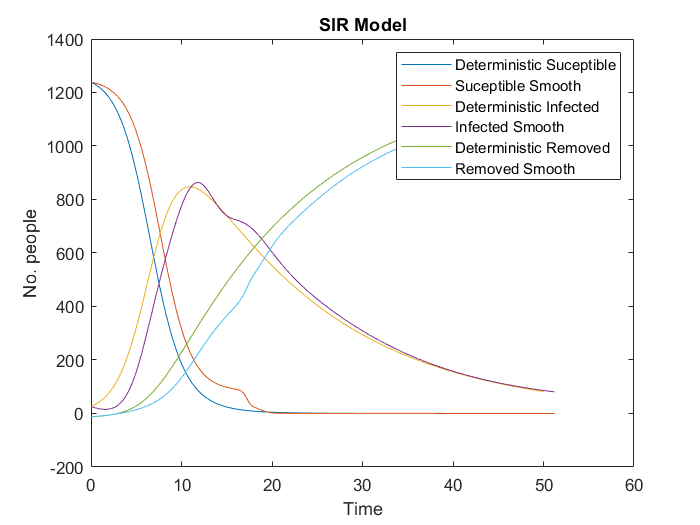

y0 = [S_smooth(1) , I_smooth(1) , R_smooth(1)];

[Stest,Itest,Rtest,ttest] = Deterministic_SIR_Model(beta_gamma(1),beta_gamma(2),N,50,y0);
plot(ttest,Stest,t,S_smooth,ttest,Itest,t,I_smooth,ttest,Rtest,t,R_smooth)
legend('Deterministic Suceptible','Suceptible Smooth','Deterministic Infected', 'Infected Smooth' ,'Deterministic Removed', 'Removed Smooth')
title('SIR Model')
xlabel('Time')
ylabel('No. people')

## Functions

Moving average

function [fun_smooth] = moving_ave(fun_dirty,n)
%This function makes 3 types of the moving average algorithm. Fowards,
%centered and bacwards. The n corresponds to the number of means you want to consider. 
    len = length(fun_dirty);
    fun_smooth = zeros(1,len); %Preallocate memory
  
    %Foward
    for ii = 1 : (n/2)+1
        fun_smooth(ii) = mean(fun_dirty(1:(n+1)));
    end

    %Centered
    for jj = (n/2)+2 : (len - (n/2))
        fun_smooth(jj) = mean(fun_dirty(jj-(n/2):jj+n/2));
    end
    
    %Backwards
    for k = (len-(n/2)):(len)
        fun_smooth(k)=mean(fun_dirty(end-(n+1):end));
    end

end

Neural Networks

function [fun_smooth,pp]=neuralnetwork_smoothfun(fn,t)
%NEURALNETWORK_SMOOTHFUN is a function that smooths out a given function
%using neural networks. It requires the NN toolbox and has 2 input
%arguments: the discrete function to smooth out and the domain vector of
%the functions. 
%fn and t are a [1xlength(t)] vectors. 

%Definir datos
[t_train,t_verify] = nn_split(t);
[f_train,f_verify] = nn_split(fn);

% Primero, vamos a definir el tipo de red
CapasOcultas = [5];  % Neuronas en cada capa oculta
Entrenamiento = 'trainlm';  
net = feedforwardnet(CapasOcultas, Entrenamiento);

% Definimos las funciones de activacion
%     compet - Competitive transfer function.         || elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.||hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function. ||netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.     ||purelin - Linear transfer function.
%     radbas - Radial basis transfer function.        ||radbasn - Radial basis normalized transfer function.
%     tribas - Triangular basis transfer function     ||satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.           ||tansig - Symmetric sigmoid transfer function.

net.layers{[1]}.transferFcn = 'logsig';


% Epocas
net.trainParam.epochs = 1000;

% Cantidad máxima de fallos consecutivos de validación
net.trainParam.max_fail = 5; %Controla el underfiting

% Entrenamos
net = train(net, t_train, f_train);

% Verificamos 
fun_nn = net(t_verify);
pp = perform(net, fun_nn, f_verify);

% Create smooth function
fun_smooth = net(t);

end


Split data

function [t_train,t_verify] = nn_split(t)
%% Function devides the dataset in 2 vectors. One for training and one for verification. 
len = length(t);

c_even = [2:2:len];
c_odd = [1:2:len];
i_even = 1;
i_odd = 1;


t_train = zeros(1,round(len/2));
t_verify = zeros(1,round(len/2));

    for ii = c_even
        t_train(i_even) = t(ii);
        i_even = i_even +1;
    end

    for jj = c_odd
        t_verify(i_odd) = t(jj);
        i_odd = i_odd +1;
    end

end


Deterministic SIR


function [S,I,R,t] = Deterministic_SIR_Model(bet,gam,N,T,y0)
%DETERMINISTIC_SIR_MODEL is a function that generates a classic SIR model
%given parameters gamma and beta. It also requires the initial number of
%agents (N) and the total days to simulate. It returns 3 discrete vectors
%that correspond to the number of S I and R. 

%- :) 



tspan = [0 T]; % Time span
[t,y] = ode45(@(t,y) odefcn(t,y,bet,gam,N), tspan, y0); % Solution for sistem of ODE.

S = y(:,1); %Suceptible
I = y(:,2); %Infectados
R = y(:,3); %Removidos


% Create a system of differential equations. 
function dydt = odefcn(t,y,bet,gam,N) 
  dydt = zeros(3,1);
  dydt(1) = -bet*y(2).*y(1)/N;
  dydt(2) = bet*y(2).*y(1)/N - gam*y(2);
  dydt(3) = gam*y(2);
end

end
